A = SessionH(G1 , "glass");
B = SessionH(G2 , "metal");
C = Sessionsmallh(G3 , "glass");
D = Sessionsmallh(G4 , "metal");
Glist = {A B C D};
names = ["image1"  , "image2"]

names = 1×2 string array
    "image1"    "image2"


f =      General model:
     f(x) = a*(x)^b +c
     Coefficients (with 95% confidence bounds):
       a =        4.31  (4.207, 4.414)
       b =         0.5  (fixed at bound)
       c =        0.01  (fixed at bound)

f =      General model:
     f(x) = a*(x)^b +c
     Coefficients (with 95% confidence bounds):
       a =        4.75  (4.654, 4.845)
       b =         0.5  (fixed at bound)
       c =        0.01  (fixed at bound)

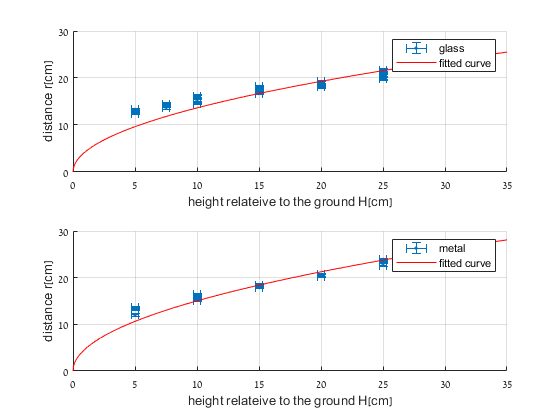

f =      General model:
     f(x) = b*(x)^a + d*x +c
     Coefficients (with 95% confidence bounds):
       a =       2.264  (-0.4037, 4.933)
       b =        1554  (-1.148e+04, 1.459e+04)
       c =  -7.295e+04  (-2.097e+05, 6.38e+04)
       d =   4.266e+04  (-3.474e+04, 1.201e+05)

f =      General model:
     f(x) = b*(x)^a + d*x +c
     Coefficients (with 95% confidence bounds):
       a =       1.318  (-0.9053, 3.542)
       b =   8.552e+04  (-9.959e+05, 1.167e+06)
       c =   7.711e+04  (-3.578e+05, 5.12e+05)
       d =  -9.362e+04  (-1.476e+06, 1.288e+06)

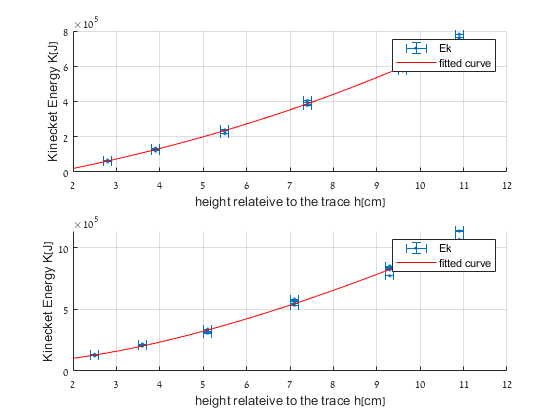

pr(@plot , Glist ,names );

names = ["var1"  , "var2"]

names = 1×2 string array
    "var1"    "var2"


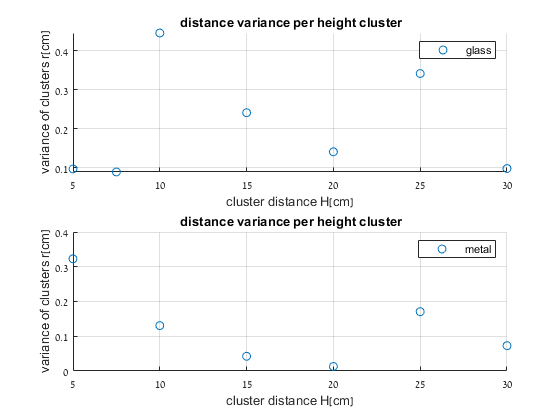

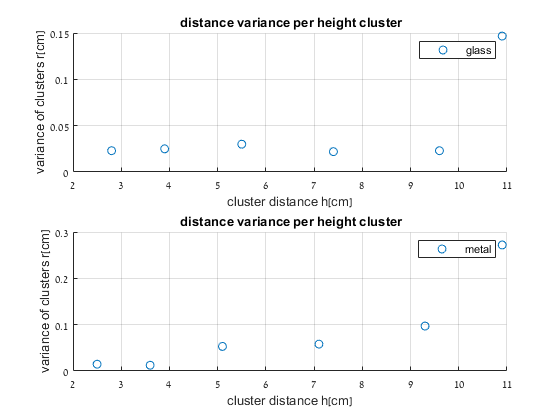

pr(@var , Glist ,names );

function pr(foo , Glist , names)
    figure();
    for i = 1:2
        for j = 1:2
            sp = subplot(2,1,j);
            grid on 
            hold(sp , 'on');
            index = 2*(i-1)+j;
            foo(Glist{index});
            hold(sp , 'off');
            if mod(j,2) == 0
                print(names{i}, "-dpng")
                figure();
            end
        end
    end
end

